Filter Specifications

180422U

Ap = 0.07;
Aa = 47;
wp1 = 500;
wp2 = 900;
wa1 = 350;
wa2 = 1000;
ws = 2400;

Bt=min((wp1-wa1),(wa2-wp2));
wc1 = wp1-Bt/2;
wc2 = wp2+Bt/2;
T=2*pi/ws;

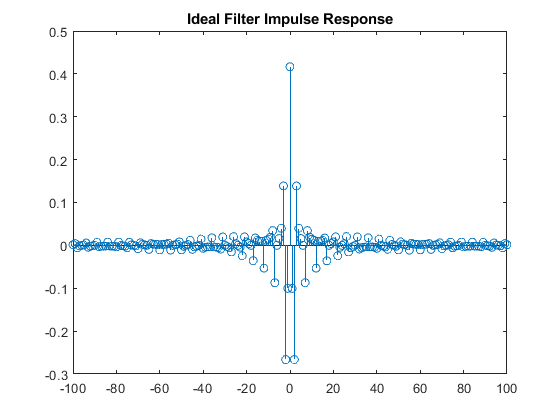

n = -100:100;
idealF = hnT(n,wc1,wc2,ws,T);
figure;
stem(n,idealF);
title('Ideal Filter Impulse Response')

deltaP=(10^(Ap/20)-1)/(10^(Ap/20)+1);
deltaA=10^(Aa/20);
delta=min(deltaP,deltaA);
ASBAtten = -20*log10(delta);
alpha=getAlpha(ASBAtten);
D= getD(ASBAtten);

N = ceil(ws*D/Bt+1);
if(mod(N,2)==0)
 N=N+1;
end
M=N-1;
tou=M/2;

Functions

function [h] = hnT(n,wc1,wc2,ws,T) 
    h=zeros(size(n));
    i1=0;
    for i = n
        i1=i1+1;
        if i==0
            h(i1)=2*(wc2-wc1)/ws;
        else
            h(i1)=(sin(wc2*i*T)-sin(wc1*i*T))/(i*pi);
        end
    end
end

%-------------------------------------------------

function [alpha] = getAlpha(ASBAtten) 
    if ASBAtten<=21
        alpha=0;
    else 
        if ASBAtten<=50
            alpha=0.5842*(ASBAtten-21)^0.4+0.07886*(ASBAtten-21);
        else
            alpha = 0.1102*(ASBAtten - 8.7);
        end
    end
end

%-------------------------------------------------

function [D]=getD(ASBAtten)
    if (ASBAtten<=21)
        D = 0.9222;
    else
        D = (ASBAtten-7.95)/14.36;
    end
end